## Modelado

syms V k_e p t
angularPos = V*k_e/p^2*exp(-p*t) - V*k_e/p*t-V*k_e/p^2

$$angularPos = \frac{V\,k_{e}\,{\mathrm{e}}^{-p\,t}}{p^{2}}-\frac{V\,k_{e}\,t}{p}-\frac{V\,k_{e}}{p^{2}}$$

angularVel = diff(angularPos,t)

$$angularVel = -\frac{V\,k_{e}}{p}-\frac{V\,k_{e}\,{\mathrm{e}}^{-p\,t}}{p}$$

## Identificación

Cargado de datos.

motor_data = load('motor_data\all_data.mat')

motor_data = struct with fields:
    motor00V: [1×1 Simulink.SimulationData.Dataset]
    motor01V: [1×1 Simulink.SimulationData.Dataset]
    motor02V: [1×1 Simulink.SimulationData.Dataset]
    motor03V: [1×1 Simulink.SimulationData.Dataset]
    motor04V: [1×1 Simulink.SimulationData.Dataset]
    motor05V: [1×1 Simulink.SimulationData.Dataset]
    motor06V: [1×1 Simulink.SimulationData.Dataset]
    motor07V: [1×1 Simulink.SimulationData.Dataset]
    motor08V: [1×1 Simulink.SimulationData.Dataset]
    motor09V: [1×1 Simulink.SimulationData.Dataset]
    motor10V: [1×1 Simulink.SimulationData.Dataset]
    motor11V: [1×1 Simulink.SimulationData.Dataset]
    motor12V: [1×1 Simulink.SimulationData.Dataset]


Ajuste lineal de los datos.

% Se preasignan los tamaños de las variables
lin_fit = ones([12 2]);
ke_mat = ones([12 1]);
p_mat = ones([12 1]);
for i = 1:12
    % Extracción de datos
    voltage = pad(num2str(i), 2, "left", '0');
    extracted = motor_data.(strcat('motor',voltage,'V')).getElement('Motor:1');
    positions = extracted.Values.Data(401:1200); % sólo 2s del motor encendido
    time = extracted.Values.Time(1:800); % tiempos re-centrados en 0
    % Ajuste lineal.
    lin_fit(i,:) = polyfit(time, positions, 1);
    ke_mat(i) = -lin_fit(i,1)^2 / (lin_fit(i,2) * i);
    p_mat(i) = -lin_fit(i,1) / lin_fit(i,2);
end

Los parámetros del sistema serán:

ke_mat, p_mat

ke_mat = 1.0e+03 *

    5.2899
    8.3536
    8.3763
    7.9683
    8.2836
    8.7220
    8.1479
    7.8191
    6.9450
    7.1908


p_mat =    69.9906
   94.6228
   88.7427
   81.8434
   84.5199
   87.6272
   81.0227
   77.6825
   68.5878
   70.6311


ke = mean(ke_mat)

ke = 7.3072e+03

p = mean(p_mat)

p = 75.7469

Construimos las matrices del sistema.

A = [0 1; 0 -p]

A =          0    1.0000
         0  -75.7469


B = [0 ke]'

B = 1.0e+03 *

         0
    7.3072


C = [1 0]

C =      1     0


D = 0;

## Comprobación

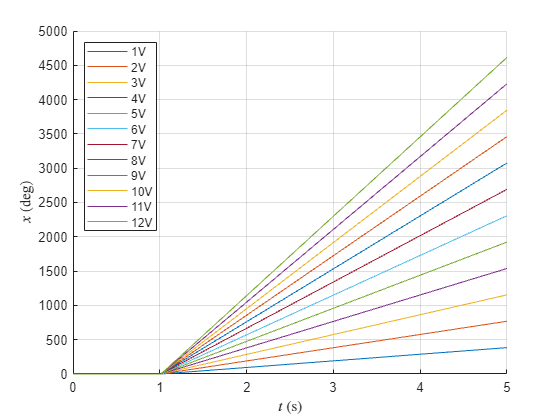

open('motor_ideal.slx')

figure(1)
clf
hold on

figure(2)
clf
hold on
for i = 1:12
    voltage = i;
    simOut = sim('motor_ideal.slx');
    time = simOut.tout;
    angPos = simOut.yout{1}.Values.Data;
    angVel = simOut.yout{2}.Values.Data;
    figure(1)
    plot(time, angPos, DisplayName=strcat(num2str(voltage),'V'))
    figure(2)
    plot(time, angVel, DisplayName=strcat(num2str(voltage),'V'))
end
figure(1)
grid on
legend(Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$x$ (deg)', Interpreter='latex')
xlim([0 5])
exportgraphics(gcf,'figuras\posicionIdeal.pdf')

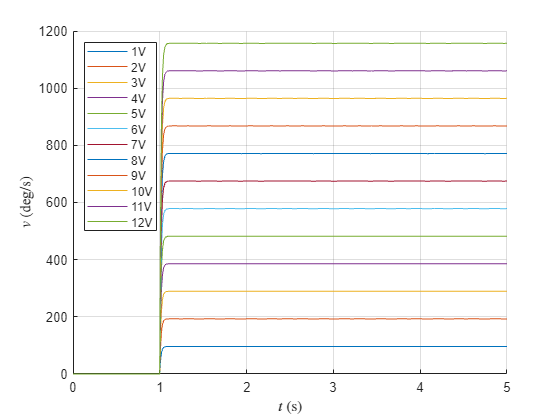

figure(2)
grid on
legend(Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$v$ (deg/s)', Interpreter='latex')
xlim([0 5])
exportgraphics(gcf,'figuras\velocidadIdeal.pdf')